## **Load data**

% Cortical amygdala
coa151 = load('coa_15_2_1.mat'); %15 odors
coa15 = load('coa_15_2_2.mat');
coaAA1 = load('coa_AAmix_2_1.mat'); %aversive/appetitve and mix
coaAA = load('coa_AAmix_2_2.mat');
coaCS1 = load('coa_CS_2_1.mat'); %concentration series
coaCS = load('coa_CS_2_2.mat');

% Piriform cortex
pcx151 = load('pcx_15_2_1.mat'); %15 odors
pcx15 = load('pcx_15_2_2.mat');
pcxAA1 = load('pcx_AAmix_2_1.mat'); %aversive/appetitve and mix
pcxAA = load('pcx_AAmix_2_2.mat');
pcxCS1 = load('pcx_CS_2_1.mat'); %concentration series
pcxCS = load('pcx_CS_2_2.mat');

% Number of odors
odors = 1:15; 
% Colors
coaC = [141,160,203] ./ 255;
pcxC = [231,138,195] ./ 255;
labelC = [82,82,82] ./ 255;

## **Extract baseline firing, change of spike counts, Fano factor and auROC**

[Bslcoa15, DeltaRspcoa15, rspMeancoa15, rspVarcoa15, ffcoa15, cvcoa15, fanoFactorcoa15, auRoccoa15, significancecoa15] = find_Baseline_DeltaRsp_FanoFactor(coa15.esp, odors);
[BslcoaAA, DeltaRspcoaAA, rspMeancoaAA, rspVarcoaAA, ffcoaAA, cvcoaAA, fanoFactorcoaAA, auRoccoaAA, significancecoaAA] = find_Baseline_DeltaRsp_FanoFactor(coaAA.esp, odors);
[Bslpcx15, DeltaRsppcx15, rspMeanpcx15, rspVarpcx15, ffpcx15, cvpcx15, fanoFactorpcx15, auRocpcx15, significancepcx15] = find_Baseline_DeltaRsp_FanoFactor(pcx15.esp, odors);
[BslpcxAA, DeltaRsppcxAA, rspMeanpcxAA, rspVarpcxAA, ffpcxAA, cvpcxAA, fanoFactorpcxAA, auRocpcxAA, significancepcxAA] = find_Baseline_DeltaRsp_FanoFactor(pcxAA.esp, odors);

## **Plot baseline**

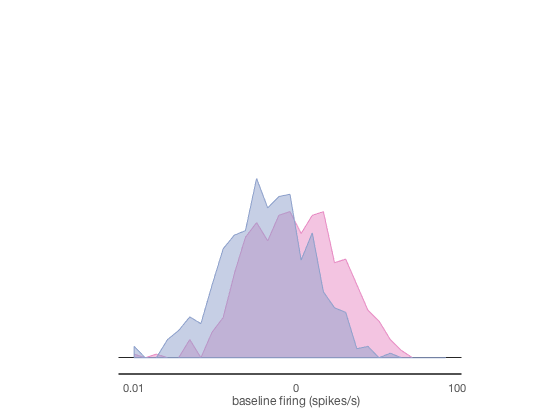

allBsl = [Bslcoa15 BslcoaAA Bslpcx15 BslpcxAA];
maxBsl = max(allBsl);
minBsl = min(allBsl);
edges = logspace(-2,2,30);
[N1,edges] = histcounts([Bslpcx15 BslpcxAA], edges,'normalization', 'probability');
[N2,edges] = histcounts([Bslcoa15 BslcoaAA], edges,'normalization', 'probability');
edges = log10(edges(1:end-1));

xMargin = 0.05 * range(edges);
bottomMargin = 0.01;
topMargin = 0.001;
leftX = min(edges);
rightX = max(edges);
blankFigure([leftX-xMargin rightX+xMargin 0-bottomMargin 0.2+topMargin]);

h1 = area(edges, N1);
h1.FaceColor = pcxC;
h1.EdgeColor = pcxC;
alpha(h1, 0.5)
hold on; 
h2 = area(edges, N2);
h2.FaceColor = coaC;
h2.EdgeColor = coaC;
alpha(h2, 0.5)


clear axP
start = floor(leftX-xMargin);
fin = ceil(rightX+xMargin);
axP.lineThickness = 2;
axP.axisLabel = 'baseline firing (spikes/s)';
axP.axisOrientation = 'h';
axP.tickLocations = [floor(leftX) 0 ceil(rightX)];
axP.tickLabelLocations = [floor(leftX) 0 ceil(rightX)];
axP.tickLabels = {'0.01', num2str(0), '100'};
axP.axisOffset = 0-bottomMargin;
axP.fontSize = 12; 
axP.color = labelC; 
AxisMMC(start, fin, axP);

## **Plot change in spikes emitted**

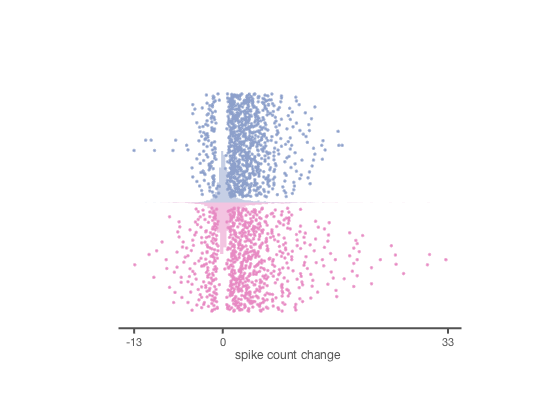

DeltaRspCOA = [DeltaRspcoa15;DeltaRspcoaAA];
DeltaRspPCX = [DeltaRsppcx15;DeltaRsppcxAA];
logSignificantCoa = [significancecoa15; significancecoaAA];
logSignificantCoa = logSignificantCoa(:);
logSignificantPcx = [significancepcx15; significancepcxAA];
logSignificantPcx = logSignificantPcx(:);

xMargin = 0.05 * range([DeltaRspCOA(:); DeltaRspPCX(:)]);
bottomMargin = 0;
topMargin = 0.001;
leftX = min([DeltaRspCOA(:); DeltaRspPCX(:)]);
rightX = max([DeltaRspCOA(:); DeltaRspPCX(:)]);
blankFigure([leftX-xMargin rightX+xMargin 0-bottomMargin 0.2+topMargin]);

distributionPlot(DeltaRspCOA(:),'histOri','right','color',coaC,'widthDiv',[2 2],'showMM',0, 'globalNorm', 1, 'xyOri', 'flipped')
distributionPlot(DeltaRspPCX(:),'histOri','left','color',pcxC,'widthDiv',[2 1],'showMM',0, 'globalNorm', 1, 'xyOri', 'flipped')
hold on
coaRsp = DeltaRspCOA;
coaRsp(logSignificantCoa == 0) = [];
pcxRsp = DeltaRspPCX;
pcxRsp(logSignificantPcx == 0) = [];
dataToPlot = {pcxRsp,coaRsp};
catIdx = [ones(length(pcxRsp),1); zeros(length(coaRsp),1)];
colori = {coaC, pcxC};
plotSpread(dataToPlot,'categoryIdx',catIdx,'categoryColors', colori, 'showMM', 0, 'xyOri', 'flipped')
alpha(0.5)

clear axP
start = floor(leftX-xMargin);
fin = ceil(rightX+xMargin);
axP.lineThickness = 2;
axP.axisLabel = 'spike count change';
axP.axisOrientation = 'h';
axP.tickLocations = [floor(leftX) 0 ceil(rightX)];
axP.tickLabels = {num2str(floor(leftX)), num2str(0), num2str(ceil(rightX))};
axP.axisOffset = 0.4;
axP.fontSize = 12; 
axP.color = labelC; 
AxisMMC(start, fin, axP);

## Plot Fano Factor

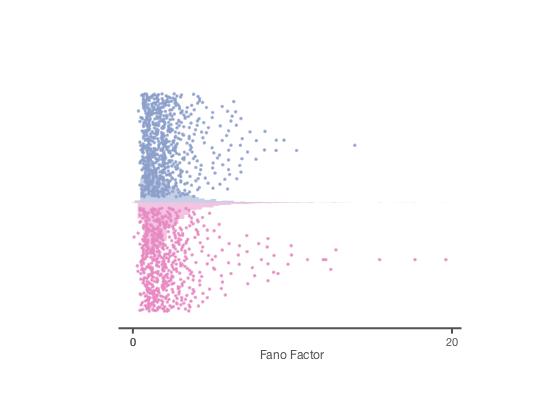

ffCOA = [abs(ffcoa15(:)); abs(ffcoaAA(:))];
%ffCOA = ffCOA(~isnan(ffCOA)); ffCOA = ffCOA(~isinf(ffCOA)); %ffCOA = ffCOA(ffCOA<40);
%logSignificantCoa = logSignificantCoa(~isnan(ffCOA)); logSignificantCoa = logSignificantCoa(~isinf(ffCOA)); %logSignificantCoa = logSignificantCoa(ffCOA<40);
ffCoaSig = ffCOA;
ffCoaSig(logSignificantCoa <1) = [];

ffPCX = [abs(ffpcx15(:)); abs(ffpcxAA(:))];
%ffPCX = ffPCX(~isnan(ffPCX)); ffPCX = ffPCX(~isinf(ffPCX)); %ffPCX = ffPCX(ffPCX<40);
%logSignificantPcx = logSignificantPcx(~isnan(ffPCX)); logSignificantPcx = logSignificantPcx(~isinf(ffPCX)); %logSignificantPcx = logSignificantPcx(ffPCX<40);
ffPcxSig = ffPCX;
ffPcxSig(logSignificantPcx < 1) = [];

xMargin = 0.05 * range([ffCoaSig; ffPcxSig]);
bottomMargin = 0;
topMargin = 0.001;
leftX = min([ffCoaSig; ffPcxSig]);
rightX = max([ffCoaSig; ffPcxSig]);
blankFigure([leftX-xMargin rightX+xMargin 0-bottomMargin 0.2+topMargin]);
distributionPlot(ffCOA(:),'histOri','right','color',coaC,'widthDiv',[2 2],'showMM',0, 'globalNorm', 1, 'xyOri', 'flipped')
distributionPlot(ffPCX(:),'histOri','left','color',pcxC,'widthDiv',[2 1],'showMM',0, 'globalNorm', 1, 'xyOri', 'flipped')
hold on
dataToPlot = {ffPcxSig,ffCoaSig};
catIdx = [ones(length(ffPcxSig),1); zeros(length(ffCoaSig),1)];
colori = {coaC, pcxC};
plotSpread(dataToPlot,'categoryIdx',catIdx,'categoryColors', colori, 'showMM', 0, 'xyOri', 'flipped')
alpha(0.5)
clear axP
start = floor(leftX-xMargin);
fin = ceil(rightX+xMargin);
axP.lineThickness = 2;
axP.axisLabel = 'Fano Factor';
axP.axisOrientation = 'h';
axP.tickLocations = [floor(leftX) 0 ceil(rightX)];
axP.tickLabels = {num2str(floor(leftX)), num2str(0), num2str(ceil(rightX))};
axP.axisOffset = 0.4;
axP.fontSize = 12; 
axP.color = labelC; 
AxisMMC(start, fin, axP);


% figure
% ecdf(ffCoaSig)
% hold on
% ecdf(ffPcxSig)
% hold off
% 

## Mean vs Variance

app1 = [rspMeancoa15(:); rspMeancoaAA(:)];
app2 = [rspVarcoa15(:); rspVarcoaAA(:)];
logSignificantCoa = [significancecoa15(:); significancecoaAA(:)];
% app1 = [rspMeancoa15(:)];
% app2 = [rspVarcoa15(:)];
% logSignificantCoa = [significancecoa15(:)];
% app1 = [rspMeancoaAA(:)];
% app2 = [rspVarcoaAA(:)];
% logSignificantCoa = [significancecoaAA(:)];
meanRspCoa = app1(logSignificantCoa==1);
varRspCoa = app2(logSignificantCoa==1);
xMargin = 0.05 * range(meanRspCoa);
yMargin = 0.05 * range(varRspCoa);
leftX = min(meanRspCoa);
rightX = max(meanRspCoa);
bottomY = min(varRspCoa);
topY = max(varRspCoa);
blankFigure([leftX-xMargin rightX+xMargin bottomY-yMargin topY+yMargin]);
plot(meanRspCoa, varRspCoa, 'o', 'MarkerSize', 3, 'MarkerEdgeColor', coaC, 'MarkerFaceColor', coaC);

clear axX
start = floor(leftX-xMargin);
fin = ceil(rightX+xMargin);
axX.lineThickness = 2;
axX.axisLabel = 'Mean (spike count)';
axX.axisOrientation = 'h';
axX.tickLocations = [floor(leftX) ceil(rightX)];
axX.tickLabels = {num2str(floor(leftX)) num2str(ceil(rightX))};
axX.axisOffset = bottomY - yMargin;
axX.fontSize = 12; 
axX.color = labelC; 
AxisMMC(start, fin, axX);

clear axY
start = floor(bottomY-yMargin);
fin = ceil(topY+yMargin);
axY.lineThickness = 2;
axY.axisLabel = 'Variance (spike count)';
axY.axisOrientation = 'v';
axY.tickLocations = [floor(bottomY) ceil(topY)];
axY.tickLabels = {num2str(floor(bottomY)) num2str(ceil(topY))};
axY.axisOffset = leftX - xMargin;
axY.fontSize = 12; 
axY.color = labelC; 
AxisMMC(start, fin, axY);
hold on
x = meanRspCoa;
y = meanRspCoa + meanRspCoa.^2 * 0.3;
fun = @(x,meanRspCoa)meanRspCoa + x(1)*meanRspCoa.^2

fun =     @(x,meanRspCoa)meanRspCoa+x(1)*meanRspCoa.^2


x0 = [0,0];
x = lsqcurvefit(fun,x0,meanRspCoa,varRspCoa);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the default value of the function tolerance.

<stopping criteria details>



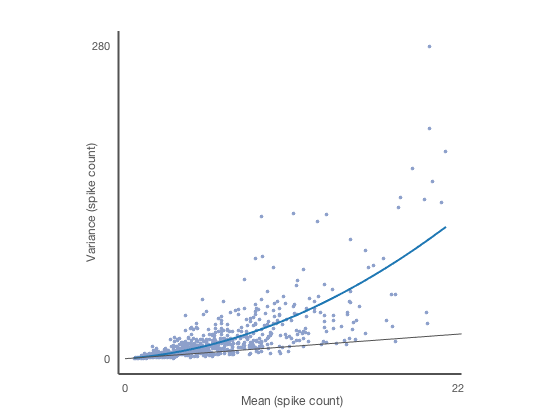

xAx = linspace(min(meanRspCoa),max(meanRspCoa));
plot(xAx,fun(x,xAx),'-', 'color', [31,120,180]/255, 'linewidth', 2)
h = line([0 max(varRspCoa)], [0 max(varRspCoa)], 'linewidth', 1, 'color', labelC);
hold off


app1 = [rspMeanpcx15(:); rspMeanpcxAA(:)];
app2 = [rspVarpcx15(:); rspVarpcxAA(:)];
logSignificantPcx = [significancepcx15(:); significancepcxAA(:)];
% app1 = [rspMeanpcx15(:)];
% app2 = [rspVarpcx15(:)];
% logSignificantPcx = [significancepcx15(:)];
% app1 = [rspMeanpcxAA(:)];
% app2 = [rspVarpcxAA(:)];
% logSignificantPcx = [significancepcxAA(:)];
meanRspPcx = app1(logSignificantPcx==1);
varRspPcx = app2(logSignificantPcx==1);
xMargin = 0.05 * range(meanRspPcx);
yMargin = 0.05 * range(varRspPcx);
leftX = min(meanRspPcx);
rightX = max(meanRspPcx);
bottomY = min(varRspPcx);
topY = max(varRspPcx);
blankFigure([leftX-xMargin rightX+xMargin bottomY-yMargin topY+yMargin]);
plot(meanRspPcx, varRspPcx, 'o', 'MarkerSize', 3, 'MarkerEdgeColor', pcxC, 'MarkerFaceColor', pcxC);


clear axX
start = floor(leftX-xMargin);
fin = ceil(rightX+xMargin);
axX.lineThickness = 2;
axX.axisLabel = 'Mean (spike count)';
axX.axisOrientation = 'h';
axX.tickLocations = [floor(leftX) ceil(rightX)];
axX.tickLabels = {num2str(floor(leftX)) num2str(ceil(rightX))};
axX.axisOffset = bottomY - yMargin;
axX.fontSize = 12; 
axX.color = labelC; 
AxisMMC(start, fin, axX);

clear axY
start = floor(bottomY-yMargin);
fin = ceil(topY+yMargin);
axY.lineThickness = 2;
axY.axisLabel = 'Variance (spike count)';
axY.axisOrientation = 'v';
axY.tickLocations = [floor(bottomY) ceil(topY)];
axY.tickLabels = {num2str(floor(bottomY)) num2str(ceil(topY))};
axY.axisOffset = leftX - xMargin;
axY.fontSize = 12; 
axY.color = labelC; 
AxisMMC(start, fin, axY);

hold on
fun = @(x,meanRspPcx)meanRspPcx(meanRspPcx<22) + x(1)*meanRspPcx(meanRspPcx<22).^2;
% fun = @(x,meanRspPcx)meanRspPcx + x(1)*meanRspPcx.^2

fun =     @(x,meanRspPcx)meanRspPcx+x(1)*meanRspPcx.^2


x0 = [0,0];
x1 = lsqcurvefit(fun,x0,meanRspPcx(meanRspPcx<22),varRspPcx(meanRspPcx<22));
xAx = linspace(min(meanRspPcx(meanRspPcx<22)),max(meanRspPcx(meanRspPcx<22)));
% x1 = lsqcurvefit(fun,x0,meanRspPcx,varRspPcx);


Local minimum possible.

lsqcurvefit stopped because the size of the current step is less than
the default value of the step size tolerance.

<stopping criteria details>



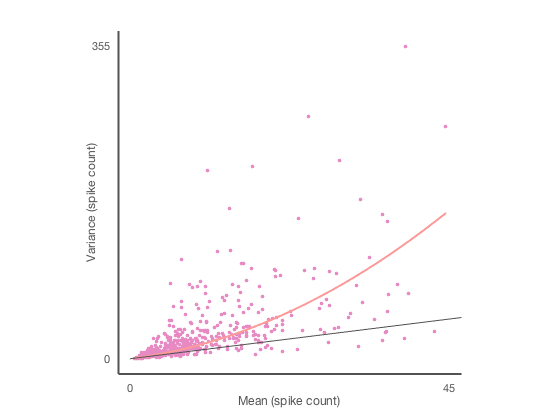

% xAx = linspace(min(meanRspPcx),max(meanRspPcx));
plot(xAx,fun(x1,xAx),'-', 'color', [251,154,153]/255, 'linewidth', 2)
h = line([0 max(varRspPcx)], [0 max(varRspPcx)], 'linewidth', 1, 'color', labelC);
hold off